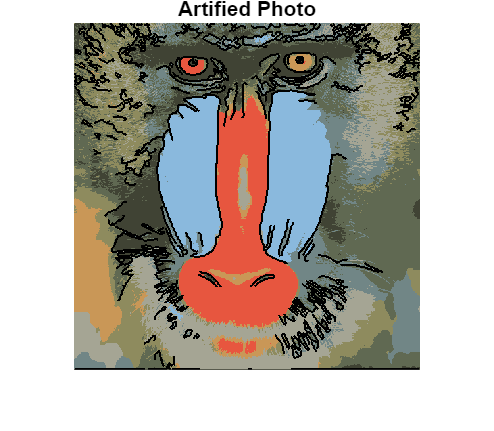

function pop(input_path, output_path)

    i = imread(input_path);
    
    [L,centers]=imsegkmeans(i,4);

    out = label2rgb(L,im2double(centers));
    out = imclose(out, strel('disk', 1));

    imwrite(out, output_path);
end

pop('baboon.png','baboon_pop.png')

pop('peppers.png','peppers_pop.png')

pop('sea.jpg','sea_pop.png')

pop('card.jpg','card_pop.png')